## Linear approximation of NON linear model

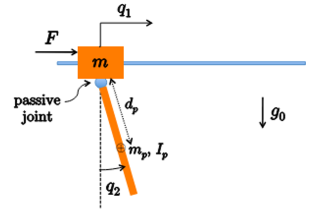

syms m_m1 m1 m2 q1 q2 dq1 dq2 d2 I2 g0 real

T_l1 = 0.5*m1*dq1^2

$$T\_l1 = \frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}$$


x2 = d2*cos(q2);
y2 = q1+d2*sin(q2);

vx2 = diff(x2,q1)*dq1 + diff(x2,q2)*dq2;
vy2 = diff(y2,q1)*dq1 + diff(y2,q2)*dq2;

T_l2 = 0.5*m2*[vx2 vy2]*[vx2; vy2;] + 0.5*I2*dq2^2;

T = T_l1+T_l2;

%% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);
M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M, 'Steps', 100);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} m_{1}+m_{2} & d_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ d_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$


% Gravity Terms
U1 = 0;
U2 = m2*g0*d2*sin(q2);
U = [U1 + U2];
g_q = simplify([diff(U, q1); diff(U, q2)], 'Steps', 100)

$$g\_q = \left(\begin{array}{c} 0\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


% Coriolis and Centrifugal terms
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = C * dq;

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d_{2}\,{\mathrm{dq}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d_{2}\,{\mathrm{dq}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$